# Creating and Customizing Pareto Charts

Pareto charts contain both bars and a line graph, where the line represents the cumulative total of the bar graphs.

### Read Aircraft Accident Data

We will use `'AircraftAccidents.mat' `to demonstrate how to create and customize pareto charts. The MAT-file contains the mechanical issues causing aircraft accidents and the number of occurrences in 2015.

load AircraftAccidents.mat

### Basic Pareto Chart

Visualize the reasons for aircraft accidents and the cumulative contribution of the reasons to the total number of accidents. From the bars of the pareto chart, we can see that the largest contributor to mechanical accidents was a powerplant issue,  followed by gear and brakes and fuel systems. Also, the total number of accidents are 150 as indicated by the accompanying line plot.

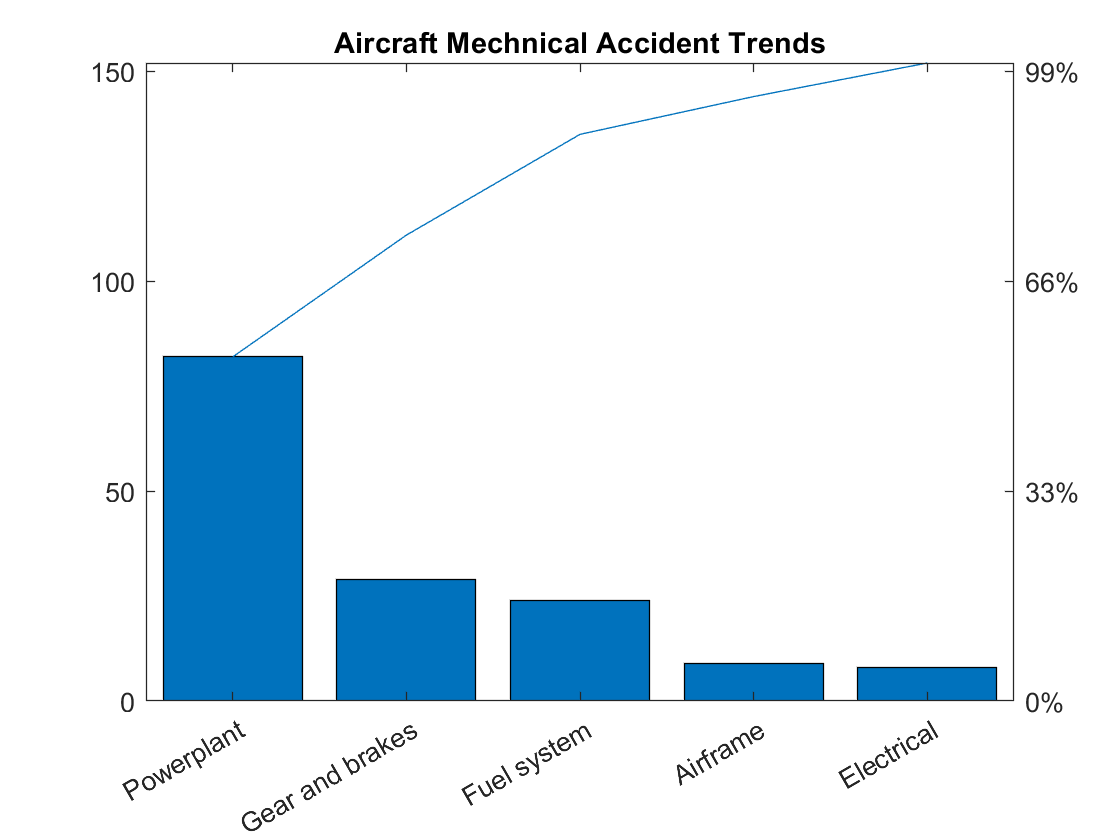

pareto(accidents,issue);
title("Aircraft Mechnical Accident Trends")

## Customization

### Customize Bar Appearance

Pareto charts are saved as 2x1 graphics array containing a Bar and Line Object. Use dot notation to access the Bar Object and change its *BarWidth*, *FaceColor*, and *FaceAlpha *properties.

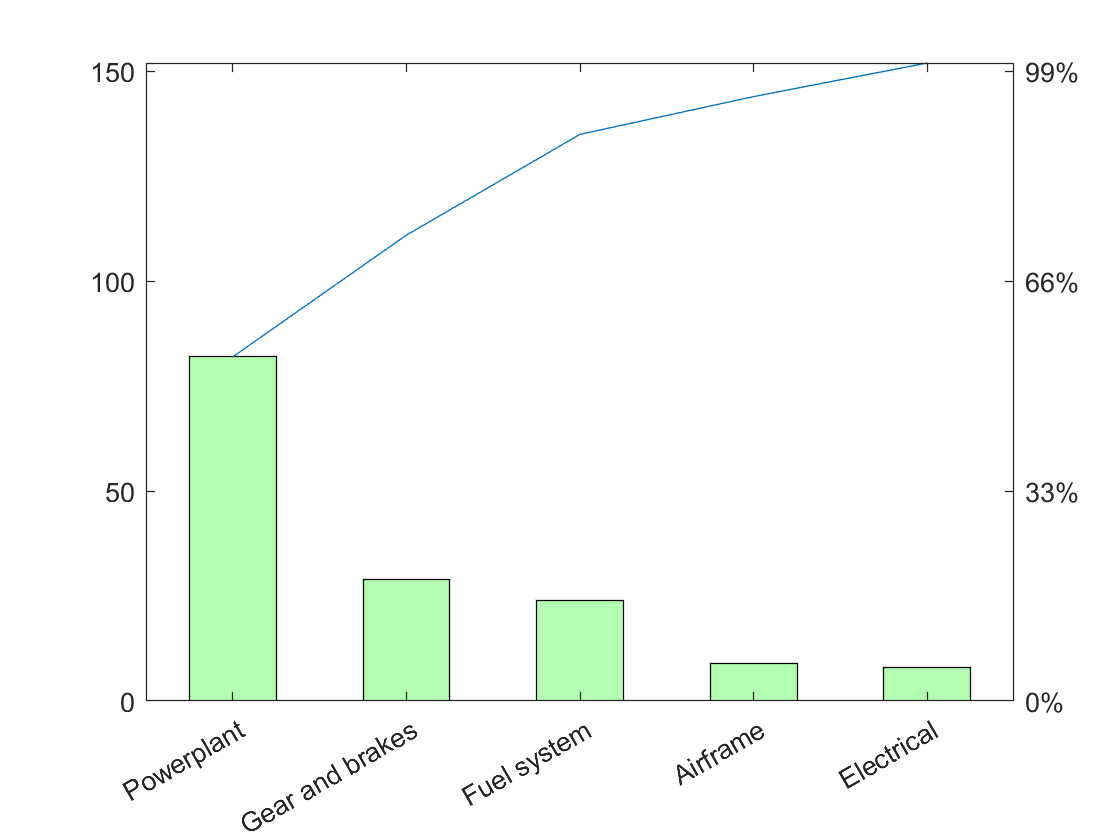

figure
p = pareto(accidents,issue);                
p(1).BarWidth = 0.5;    % Specify bar width between 0.1 and 1
p(1).FaceColor = "green";         % Specify bar color
p(1).FaceAlpha = 0.3;   % Specify bar transparency between 0 and 1

### Customize Line Appearance

Use dot notation to access the Line Object and change its *LineStyle* and *LineWidth* properties. Add axes labels and a title.

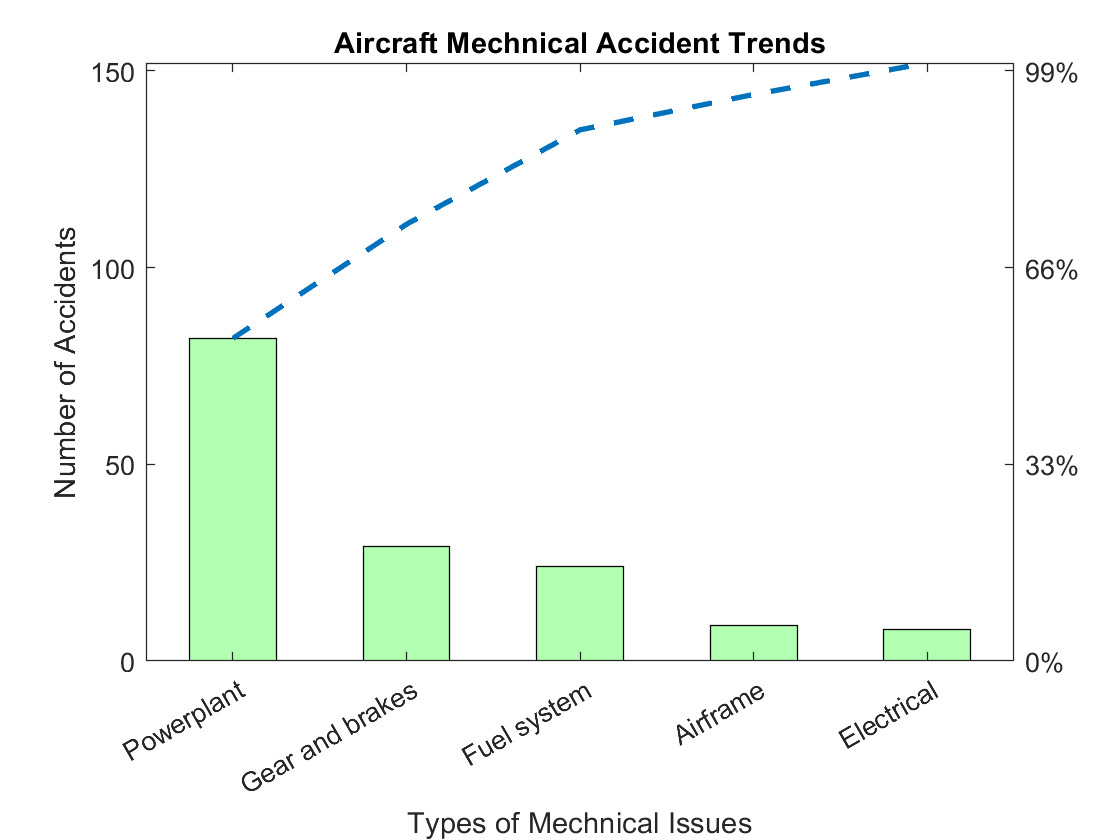

p(2).LineStyle = '--';         % Specify line style          
p(2).LineWidth = 2;   % Specify line width                     
title("Aircraft Mechnical Accident Trends")
xlabel("Types of Mechnical Issues")
ylabel("Number of Accidents")

## **Additional Information**

### **Get All Bar and Line Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a Bar or Line, uncomment the following code. View or modify these properties using dot notation.

% get(p(1))
% get(p(2))

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[Pareto Chart](https://www.mathworks.com/help/matlab/ref/pareto.html?searchHighlight=pareto&s_tid=srchtitle)

Copyright (c) 2021, The MathWorks, Inc.